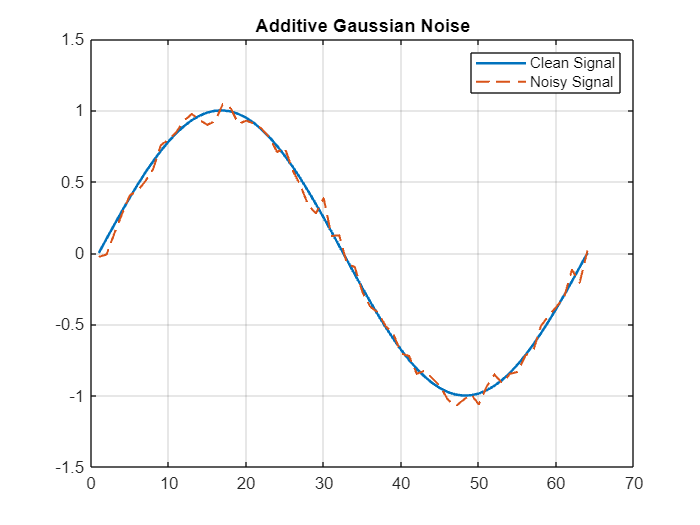

n = 64;
t = linspace(0, 1, n)';
x = sin(2*pi*t);

sigma = 0.05;

[y_noisy, noise] = add_gaussian_noise(x, sigma);

figure;
plot(x, 'LineWidth', 1.5); hold on;
plot(y_noisy, '--', 'LineWidth', 1.2);
legend('Clean Signal', 'Noisy Signal');
title('Additive Gaussian Noise');
grid on;

function [y_noisy, noise] = add_gaussian_noise(y, sigma, rng)
    if nargin < 3 || isempty(rng)
        noise = sigma * randn(size(y));
    else
        noise = sigma * randn(rng, size(y));
    end

    y_noisy = y + noise;
end